# DIP CAPSTONE PROJECT

### Title: Image contrast enhancement using triple clipped dynamic histogram equalisation based on standard deviation

### Team Members:

### Saraf Parth Vikrant - 19EE38020

### Ansari Md. Saad - 19EE38023

### Swarnava Bag - 19EE38018

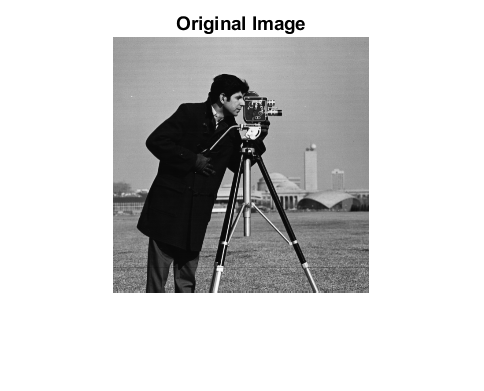

clc
clear 
close all;
img = double(imread('cameraman.tif'));
% img = double(rgb2gray(img)) % if we take a RGB image(colored image)

imshow(uint8(img))
title("Original Image")

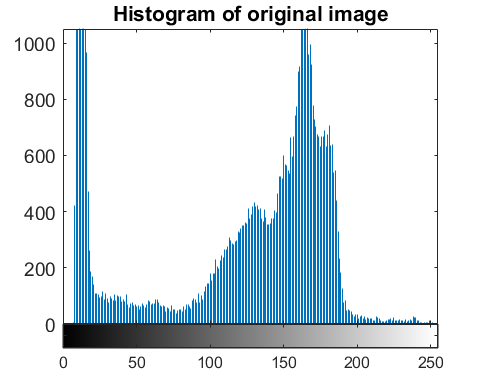

[M,N] = size(img);

imhist(uint8(img));
title("Histogram of original image");

h_orig = imhist(uint8(img));

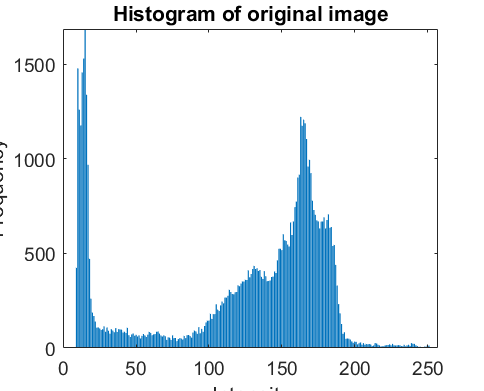

% 1 based indexing

% Calculating the mean and variance of the original image
L = length(h_orig);
mu = (sum((0:L-1)'.*h_orig))/(M*N);
variance = mean(mean((img-mu).^2));
sd = sqrt(variance);    % Standard deviation = sqrt(variance)

% All intensity levels are 1-indexed
m0 = 1 + min(min(img));     % Minimum intensity of image
m1 = 1 + floor(mu - 0.43 * sd);
m2 = 1 + floor(mu + 0.43 * sd);
m3 = 1 + max(max(img));     % Maximum intensity of image

% Created the Subhistograms

h1 = h_orig(1:m1-1);
h2 = h_orig(m1:m2-1);
h3 = h_orig(m2:L);

% Calculated the thresholds by taking the mean across
% that particular histogram
Thresh1 = sum(h1) / (m1 - m0);  % Calculating over range [m0, m1-1],
% but from [1, m0-1], the frequency of the intensity values is 0
Thresh2 = sum(h2) / (m2 - m1);
Thresh3 = sum(h3) / (m3 + 1 - m2);

% Histogram clipping above threshold
idx1 = find(h1>=Thresh1);
h1(idx1) = Thresh1;
C1_clipped = cumsum(h1);

idx2 = find(h2>=Thresh2);
h2(idx2) = Thresh2;
C2_clipped = cumsum(h2);

idx3 = find(h3>=Thresh3);
h3(idx3) = Thresh3;
C3_clipped = cumsum(h3);

% Calculating the Cumulative Distribution
% function for the clipped histograms

% Over all the 3 regions
cdf_lower = C1_clipped / sum(h1);
cdf_mid = C2_clipped / sum(h2);
cdf_high = C3_clipped / sum(h3);

% Mapping each partition to a new dynamic range for each subhistogram
n0 = 1;
n1 = 1+ ((L-1) * (m1 - m0)) / (m3 - m0 + 1);
n2 = 1+ n1 + ((L-1) * (m2 - m1)) / (m3 - m0 + 1);
n3 = 1+ (L-1);

% Transfer function of each subhistogram
F_lower = uint8((n1-1)*cdf_lower);
F_mid = uint8(n1 + (n2-1-n1)*cdf_mid);
F_high = uint8(n2 + (n3-n2)*cdf_high);

T = [F_lower; F_mid; F_high]; % Overall transformation function 

img_TCDHE_SD = T(1+int32(img)); % Enhanced image
img_TCDHE_SD = img_TCDHE_SD - 1;

% Taking care of intensity value = 256 and 1-indexing
hfinal = imhist(img_TCDHE_SD);
bar(h_orig);
ylim([0 max(hfinal)]);
xlabel("Intensity")
ylabel("Frequency")
title("Histogram of original image");

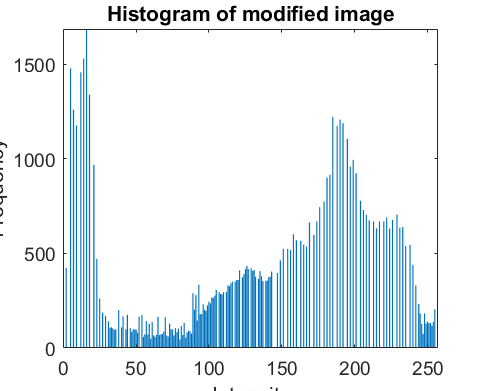

bar(hfinal);
ylim([0 max(hfinal)]);
xlabel("Intensity")
ylabel("Frequency")
title("Histogram of modified image");

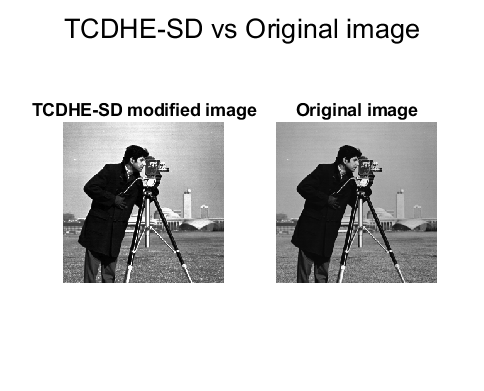

subplot(121);
imshow(img_TCDHE_SD);
title("TCDHE-SD modified image");
subplot(122);
sgtitle("TCDHE-SD vs Original image")
imshow(uint8(img));
title("Original image");

% Measuring the image Entropy by entropy
pdf_orig = h_orig/sum(h_orig) + eps;        % Preventing log (0) error by taking small eps
Entropy_orig = -1*sum(pdf_orig.*log2(pdf_orig));     % Entropy = - Sum(pi*log(pi))

% Measuring the image Entropy by entropy
pdf_TCDHE = hfinal/sum(hfinal) + eps;
Entropy_TCDHE = -1*sum(pdf_TCDHE.*log2(pdf_TCDHE));

## **Comparison of TCDHE_SD with GHE, BHE, DHE**

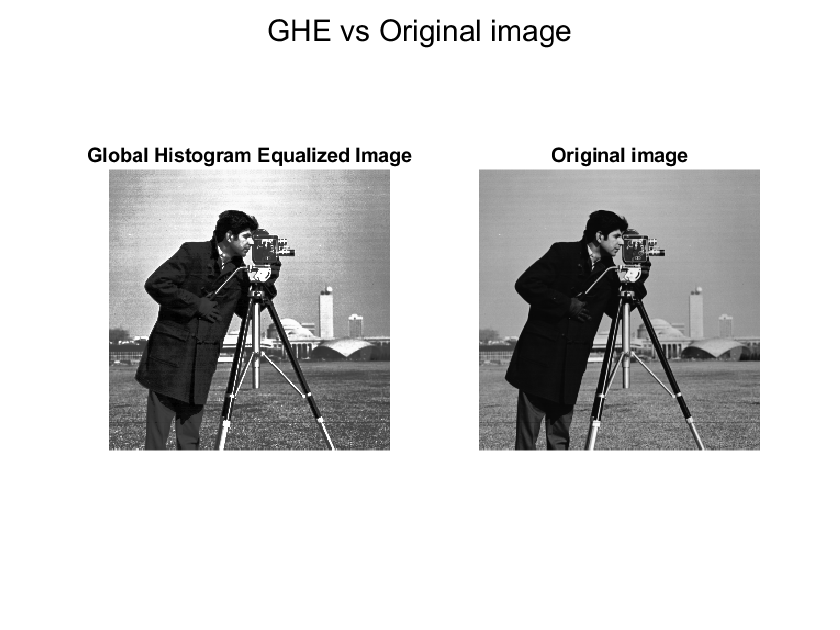

% Global Histogram Equalization

% Calculated the cumulative histogram function for original image
c_orig = cumsum(h_orig);
T_ghe = Equalize(h_orig, c_orig, 0, L-1);   % Global Histogram Equalization
img_ghe = uint8(T_ghe(1+uint8(img)));
% Global histogram Equalized image

figure(3);
subplot(121);
imshow(img_ghe);
title("Global Histogram Equalized Image");
subplot(122);
imshow(uint8(img));
sgtitle("GHE vs Original image")
title("Original image");

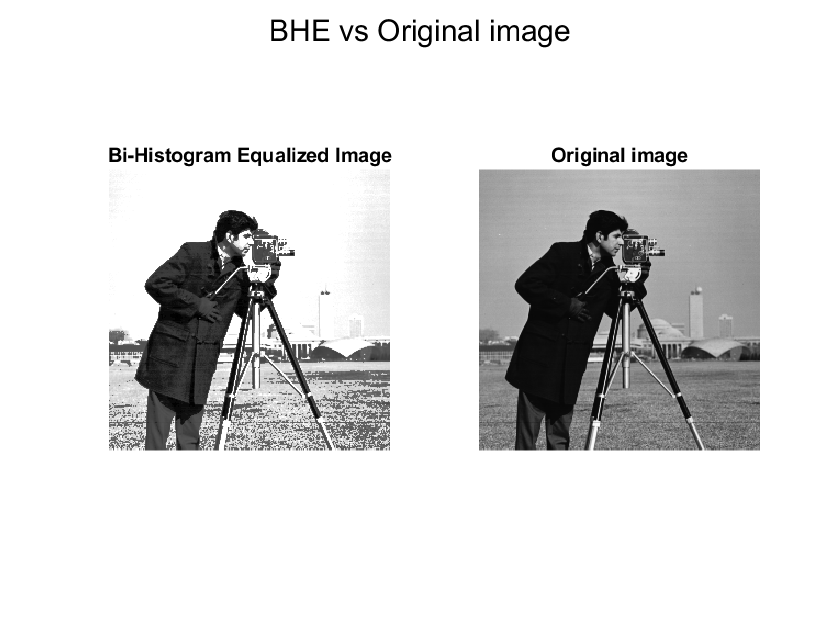


h_ghe = imhist(img_ghe);

% Measuring the image Entropy by entropy
pdf_ghe = h_ghe/sum(h_ghe) + eps;
Entropy_ghe= -1*sum(pdf_ghe.*log2(pdf_ghe));


% Bihistogram Equalization

% Partitioning the histogram into 2 parts based 
% on the mean intensity of the image
mu_g = round(sum((0:L-1)'.*h_orig) / sum(h_orig));
% Equalized each subhistogram
T_bhe1 = Equalize(h_orig, c_orig, 0, mu_g);
T_bhe2 = Equalize(h_orig, c_orig, mu_g + 1, L-1);
T_bhe = [T_bhe1; T_bhe2];

% Created a tranformed image
% according to the transformation map
img_bhe = uint8(T_bhe(1+uint8(img)));

figure(4);
subplot(121);
imshow(img_bhe);
title("Bi-Histogram Equalized Image");
subplot(122);
imshow(uint8(img));
title("Original image");
sgtitle("BHE vs Original image")

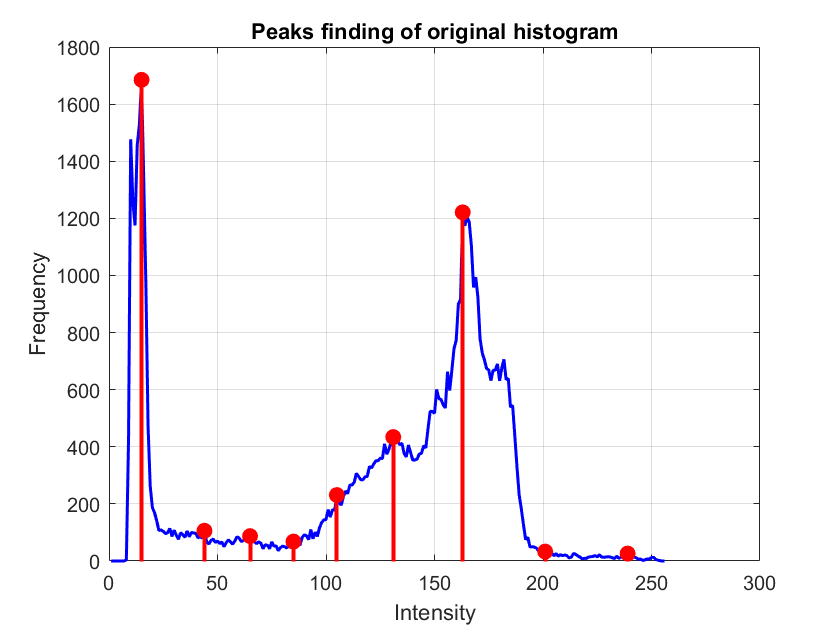


h_bhe = imhist(img_bhe);

% Measuring the image Entropy by entropy
pdf_bhe = h_bhe/sum(h_bhe) + eps;
Entropy_bhe= -1*sum(pdf_bhe.*log2(pdf_bhe));


% Dynamic Histogram Equalization (DHE)

Peaks = PeakFind(h_orig);
figure(5);
plot(h_orig, 'b', 'LineWidth', 1.5);
hold on;
stem(Peaks, h_orig(Peaks), 'r', 'filled', "LineWidth", 2);
grid on;
xlabel("Intensity")
ylabel("Frequency")
title("Peaks finding of original histogram");

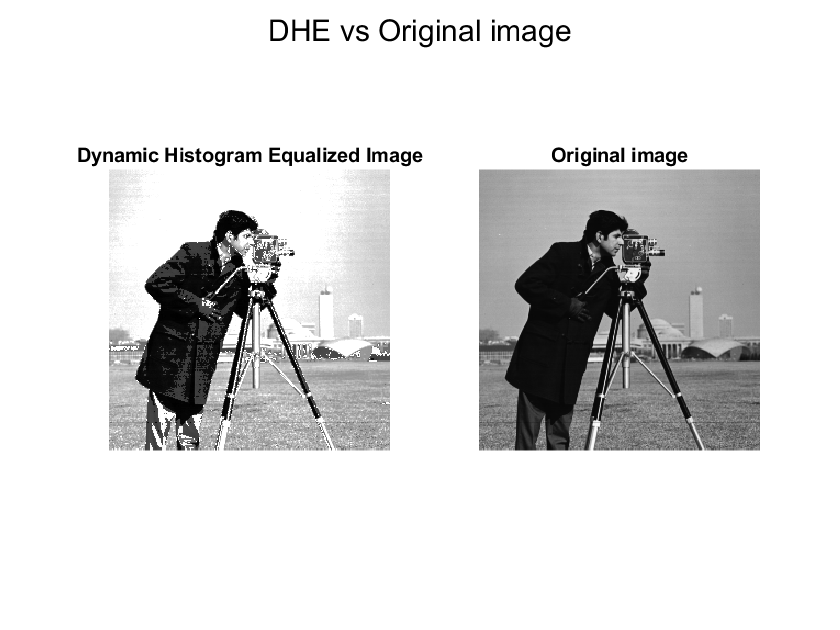


figure(6);
T_dhe = DHE(h_orig, Peaks)';
img_dhe = uint8(T_dhe(1+uint8(img)));

subplot(121);
imshow(img_dhe);
title("Dynamic Histogram Equalized Image")
subplot(122);
imshow(uint8(img));
title("Original image");
sgtitle("DHE vs Original image")


h_dhe = imhist(img_dhe);

% Measuring the image Entropy by entropy
pdf_dhe = h_dhe/sum(h_dhe) + eps;
Entropy_dhe= -1*sum(pdf_dhe.*log2(pdf_dhe));

% Brightness Preserving Dynamic Fuzzy Histogram Equalization

[img_BPDFHE, T_BPDFHE] = fcnBPDFHE(img);

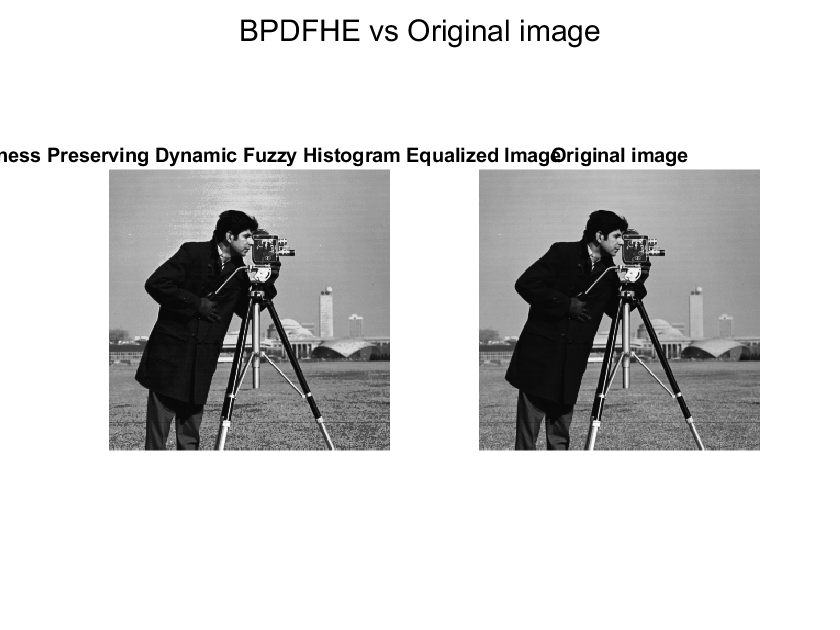

figure(7);
% T_bpdfhe = DHE(h_orig, Peaks)'
% img_dhe = uint8(T_dhe(uint8(img)));

subplot(121);
imshow(uint8(img_BPDFHE));
title("Brightness Preserving Dynamic Fuzzy Histogram Equalized Image");
subplot(122);
imshow(uint8(img));
title("Original image");
sgtitle("BPDFHE vs Original image")


h_BPDFHE = imhist(uint8(img_BPDFHE));

% Measuring the image Entropy by entropy
pdf_BPDFHE = h_BPDFHE/sum(h_BPDFHE) + eps;
Entropy_BPDFHE= -1*sum(pdf_BPDFHE.*log2(pdf_BPDFHE));

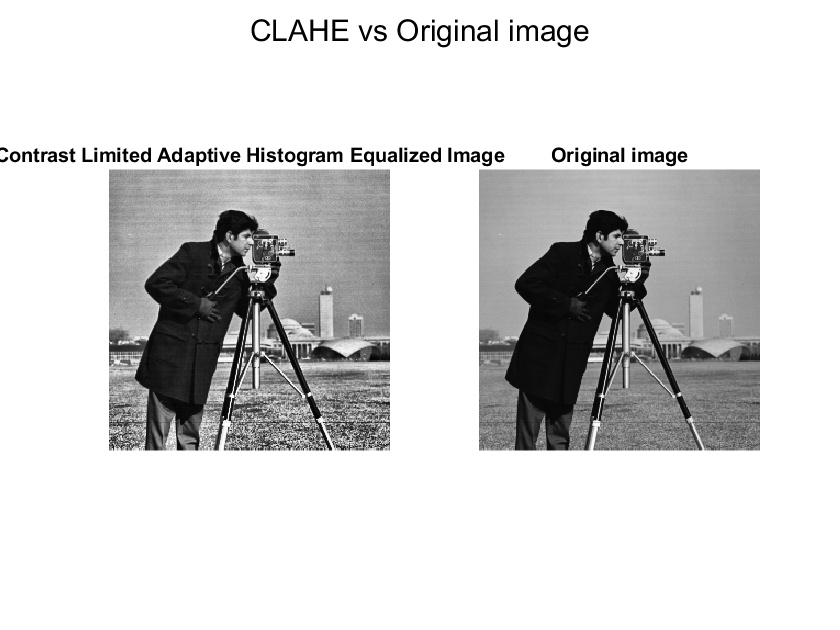

% CLAHE

% Contrast Limited Adaptive Histogram Equalization

img_CLAHE = adapthisteq(uint8(img));    % Using inbuilt function
h_CLAHE = imhist(uint8(img_CLAHE));

figure(8);
subplot(121);
imshow(uint8(img_CLAHE));
title("Contrast Limited Adaptive Histogram Equalized Image");
subplot(122);
imshow(uint8(img));
title("Original image");
sgtitle("CLAHE vs Original image")


h_CLAHE = imhist(uint8(img_CLAHE));

% Measuring the image Entropy by entropy
pdf_CLAHE = h_CLAHE/sum(h_CLAHE) + eps;
Entropy_CLAHE= -1*sum(pdf_CLAHE.*log2(pdf_CLAHE));

% Results display and comparisons

disp("The entropy of original image is : " + Entropy_orig)

The entropy of original image is : 7.0097


disp("The entropy of TCDHE-SD image is : " + Entropy_TCDHE)

The entropy of TCDHE-SD image is : 6.9052


disp("The entropy of GHE image is : " + Entropy_ghe)

The entropy of GHE image is : 6.7699


disp("The entropy of BHE image is : " + Entropy_bhe)

The entropy of BHE image is : 4.9364


disp("The entropy of DHE image is : " + Entropy_dhe)

The entropy of DHE image is : 5.3667


disp("The entropy of BPDFHE image is : " + Entropy_BPDFHE)

The entropy of BPDFHE image is : 6.711


disp("The entropy of CLAHE image is : " + Entropy_CLAHE)

The entropy of CLAHE image is : 7.5315


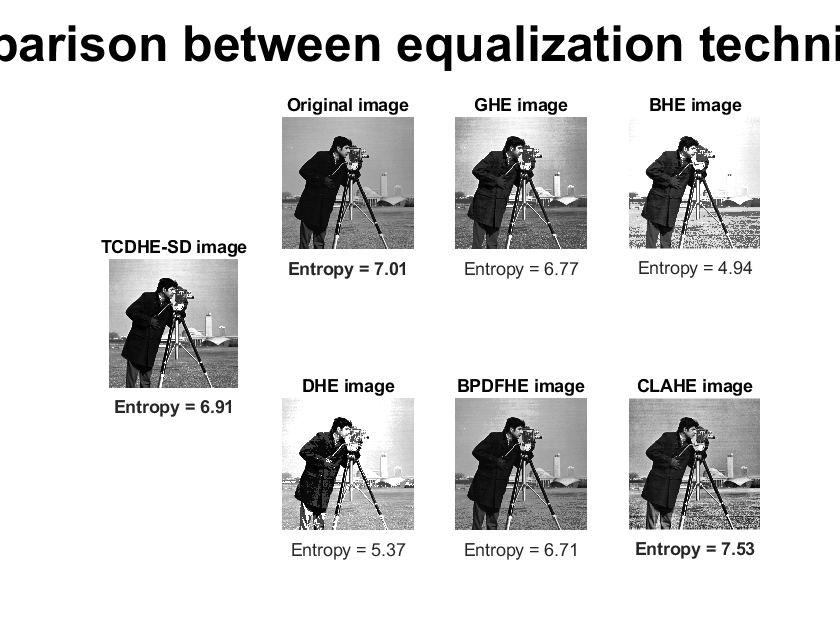


figure(9);

subplot(141);
imshow(uint8(img_TCDHE_SD));
title("TCDHE-SD image");
xlabel(sprintf("Entropy = %0.3g", Entropy_TCDHE), 'VerticalAlignment', "baseline", 'fontweight','bold');
subplot(242);
imshow(uint8(img));
title("Original image");
xlabel(sprintf("Entropy = %0.3g", Entropy_orig), 'VerticalAlignment', "baseline", 'fontweight','bold');
subplot(243);
imshow(uint8(img_ghe));
title("GHE image");
xlabel(sprintf("Entropy = %0.3g", Entropy_ghe), 'VerticalAlignment', "baseline");
subplot(244);
imshow(uint8(img_bhe));
title("BHE image");
xlabel(sprintf("Entropy = %0.3g", Entropy_bhe), 'VerticalAlignment', "baseline");
subplot(246);
imshow(uint8(img_dhe));
title("DHE image");
xlabel(sprintf("Entropy = %0.3g", Entropy_dhe), 'VerticalAlignment', "baseline");
subplot(247);
imshow(uint8(img_BPDFHE));
title("BPDFHE image");
xlabel(sprintf("Entropy = %0.3g", Entropy_BPDFHE), 'VerticalAlignment', "baseline");
subplot(248);
imshow(uint8(img_CLAHE));
title("CLAHE image");
xlabel(sprintf("Entropy = %0.3g", Entropy_CLAHE), 'VerticalAlignment', "baseline", 'fontweight','bold');
sgtitle("Comparison between equalization techniques", 'fontweight','bold', 'fontsize', 25)

function k = DHE(h, peaks)
    points = [0, peaks,256];
    k = zeros(1,256,'uint8');
    for i = 2:length(points)
        k(1,points(i-1)+1:points(i)) = Equalize(h,cumsum(h),points(i-1),points(i)-1);
    end
end 

function Transformation = Equalize(h, c, startI, endI)
    
    if startI > length(h) - 1 || endI > length(h) - 1
        Transformation = [];
    else
        % 1 - indexing
        startI = startI + 1;
        endI = endI + 1;
        
        Transformation = zeros(size(c), 'uint8');
        % Initialize
        
        if startI == 1
            LowerCumulative = 0;
        else
            LowerCumulative = c(startI - 1);
        end
        % Equalizing the histogram on the intensity range startI:endI
        % Sum of h(i) for i from [startI:endI] = C(endI) - C(startI-1)
        Transformation = startI - 1 + (c.*(endI - startI))/(c(endI) - LowerCumulative);
        Transformation = Transformation(startI : endI);
    end
end

function locs = PeakFind(h)
    L = length(h);
    first_der = zeros(L,1);
    second_der = zeros(L,1);
    valid = zeros(L,1,'uint8');
    for k = 2:L-1
        if k-1>0 && k+1<=L 
            first_der(k) = (h(k+1)-h(k-1))/2;
        end
        if k>=3 && k<=L-2
            second_der(k) = (first_der(k+1)-first_der(k-1))/2;
        end
    end
    
    for k = 3:L-2
        % For maxima
        if sign(first_der(k-1))*sign(first_der(k+1))<0 && second_der(k)<0
                valid(k) = 1;
        end
    end
    for k = 3:L-2
        % For continuous maximas, take the maximum one
        if valid(k)==1 && valid(k+1)==1
            if h(k)>h(k+1)
                valid(k+1)=0;
            else 
                valid(k) = 0;
            end
        end
    end
    
    max_peak = double(valid).*h;
    [mp,ind] = sort(max_peak,'descend');
    locs(1) = ind(1);
    for i = 2:size(ind)
        if sum(abs(locs-ind(i))<20)==0
            locs(end+1) = ind(i);
        end
    end
end